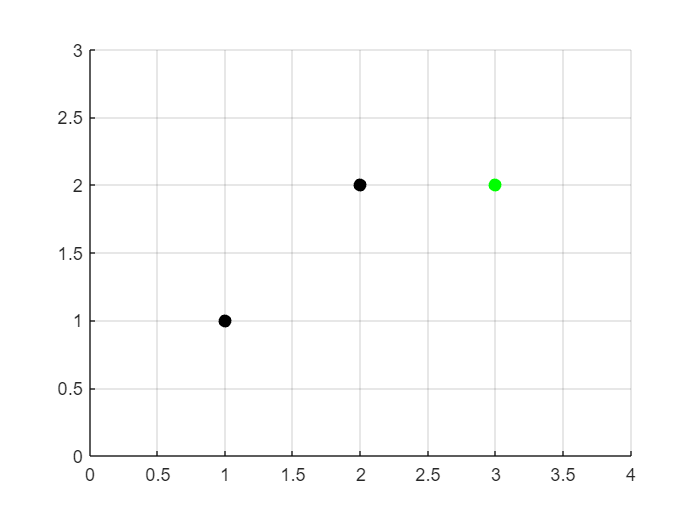

P1=[1,1]'; P2=[3,2]';
plot(P1(1),P1(2),'.k','MarkerSize',21)
hold on; grid on; 
%to ask to use monometric system in Matlab
plot(P2(2),P2(2),'.k','MarkerSize',21)

Matlab non usa un sistema monometrico. Per forzare un sistema diverso bisogna usare "axis equal"

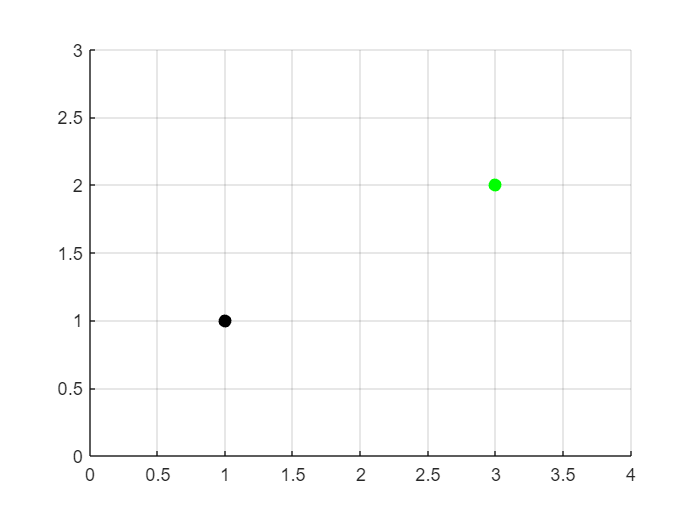

figure(1); clf
hold on; grid on; axis equal
plot(P1(1),P1(2),'.k','MarkerSize',21)
plot(P2(1),P2(2),'.g','MarkerSize',21)
axis([0 4 0 3])

% plot([P1(1) P2(1)],[P1(2) P2(2)],'r')


vediamo la differenza tra simbolico e numerico

figure(2); clf;
hold on; grid on; axis equal
plot(P1(1),P1(2),'.k','MarkerSize',21)
plot(P2(1),P2(2),'.g','MarkerSize',21)
axis([0 4 0 3])

syms lambda real
P=P1+ lambda*(P2 - P1) % segment

$$P = \left(\begin{array}{c} 2\,\lambda +1\\ \lambda +1 \end{array}\right)$$

%P is a symbolic object
ezplot(P(1),P(2),[0 1]); %In this case in the plot there is a notation (x and y). 
% Also there is the x and y formula on top

If we want to change the color what we can do is this:

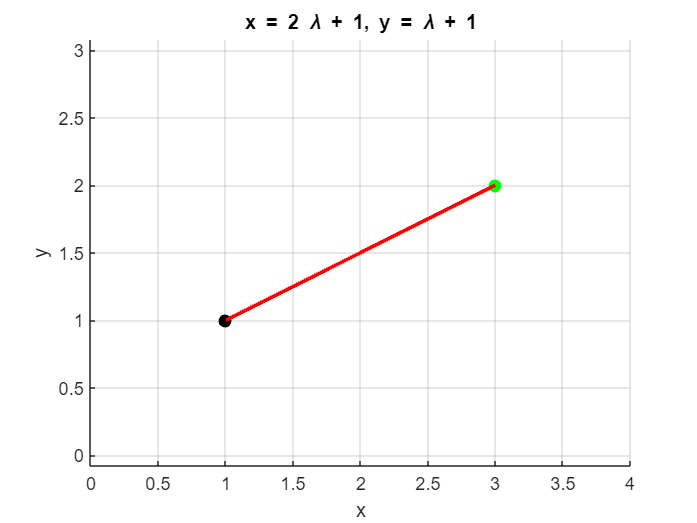

h=ezplot(P(1),P(2),[0 1]); set(h,Color="r",LineWidth=2)

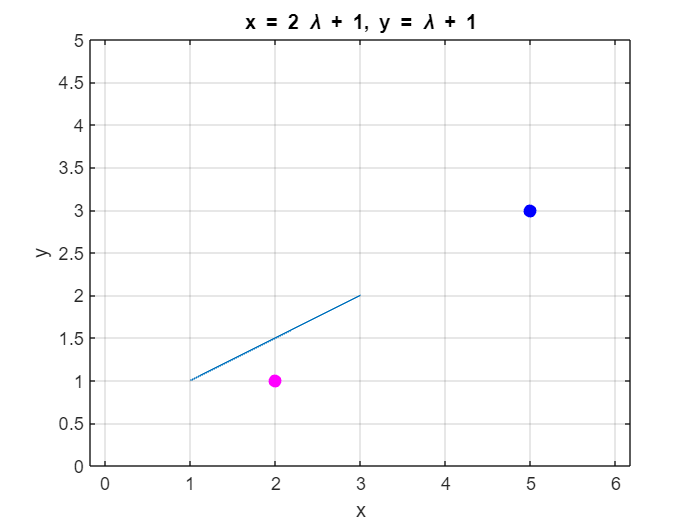

P3=[2 1]';
plot(P3(1),P3(2),'.m','MarkerSize',21)

%Let's check if the point is on the line, spanned by the two points of the
%segments and then if the lambda is between 0 and 1.
%Since the line has the equation P=P1 + lambda*(P2-P1) for real lambda
%If i put p3 here, on the line <==> P3= P1 + lambda*(P2-P1)
%This mean that must exists a lambda such as that the equation holds
% P3=P1 + lambda*(P2-P1) <==> lambda = (P3 - P1) / (P2 - P1) %But pay
% attentions: they are vectors. This operation doesn't apply to vectors: we
% need the points
%In matlab you need to use the points before the operations
lambda = (P3-P1)./(P2-P1)

lambda =     0.5000
         0


% Two different values, this means that no lambda exists, such as that P3
% so that the component must be equal, the same. 
if lambda(1)==lambda(2)
    disp("P3 on the line")
else
    disp("P3 NOT on the line")
end

P3 NOT on the line



%Now try with P3
P3=[5 3]';
lambda=(P3-P1)./(P2-P1)

lambda =      2
     2



if lambda(1)==lambda(2)
    disp("P3 on the line")
else
    disp("P3 NOT on the line")
end

P3 on the line


figure(3); clf;
syms lambda real
P=P1+ lambda*(P2 - P1) % segment

$$P = \left(\begin{array}{c} 2\,\lambda +1\\ \lambda +1 \end{array}\right)$$

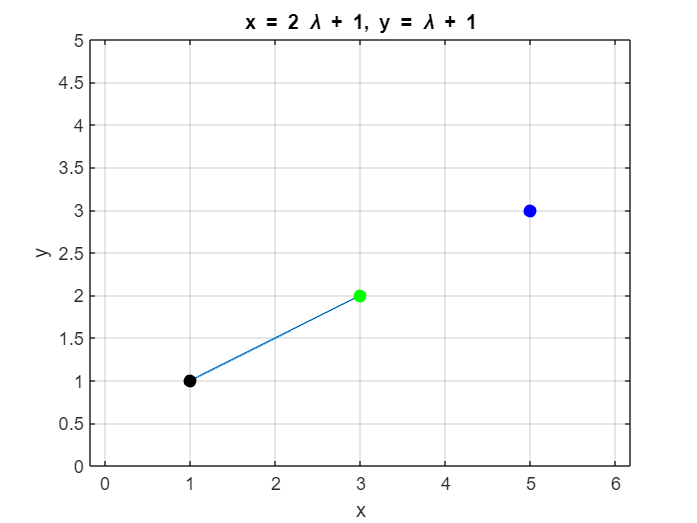

ezplot(P(1),P(2),[0 1]);
axis([0 6 0 5])
hold on; grid on; axis equal
plot(P1(1),P1(2),'.k','MarkerSize',21)
plot(P2(1),P2(2),'.g','MarkerSize',21)
plot(P3(1),P3(2),'.b','MarkerSize',21)


%Assignment: read the remaining slide and do examples in matlab